% Convex Optimization
% Hw5
% Q4_b

clear;
clc;
close all;

% Initialization:
n = 13; 
m = [1, 5, 6, 15, 18, 20, 22, 11, 22, 8, 9, 4, 2];
N = sum(m);

i = 2 : 1 : n-1;
cvx_begin
    variable p(n)
    maximize ( m*log(p) ) % gives distribution of p

CVX Warning:
   Models involving "log" or other functions in the log, exp, and entropy
   family are solved using an experimental successive approximation method.
   This method is slower and less reliable than the method CVX employs for
   other models. Please see the section of the user's guide entitled
       <a href="file:///A:\Uni_Arshad\Term 2\Convex\cvx MATLAB\cvx\doc\advanced.html#the-successive-approximation-method">The successive approximation method</a>
   for more details about the approach, and for instructions on how to
   suppress this warning message in the future.


    subject to
        p(:) >=0 ;    
        ones(1,n)*p == 1;    % Sum(p) = 1 ; PDF function
        (p(i)) >= 0.5*((p(i+1)) + (p(i-1))); % Given Constraint
cvx_end

 
Successive approximation method to be employed.
   SDPT3 will be called several times to refine the solution.
   Original size: 65 variables, 38 equality constraints
   13 exponentials add 91 variables, 52 equality constraints
-----------------------------------------------------------------
 Cones  |             Errors              |
Mov/Act | Centering  Exp cone   Poly cone | Status
--------+---------------------------------+---------
 13/ 13 | 3.537e+00  1.542e+00  0.000e+00 | Solved
 13/ 13 | 1.351e+00  1.689e-01  0.000e+00 | Solved
 13/ 13 | 1.807e-01  2.685e-03  0.000e+00 | Solved
 13/ 13 | 1.435e-02  1.669e-05  0.000e+00 | Solved
 12/ 13 | 1.746e-03  2.367e-07  0.000e+00 | Solved
  0/  2 | 1.519e-04  4.729e-10  0.000e+00 | Solved
-----------------------------------------------------------------
Status: Solved
Optimal value (cvx_optval): -337.004
 


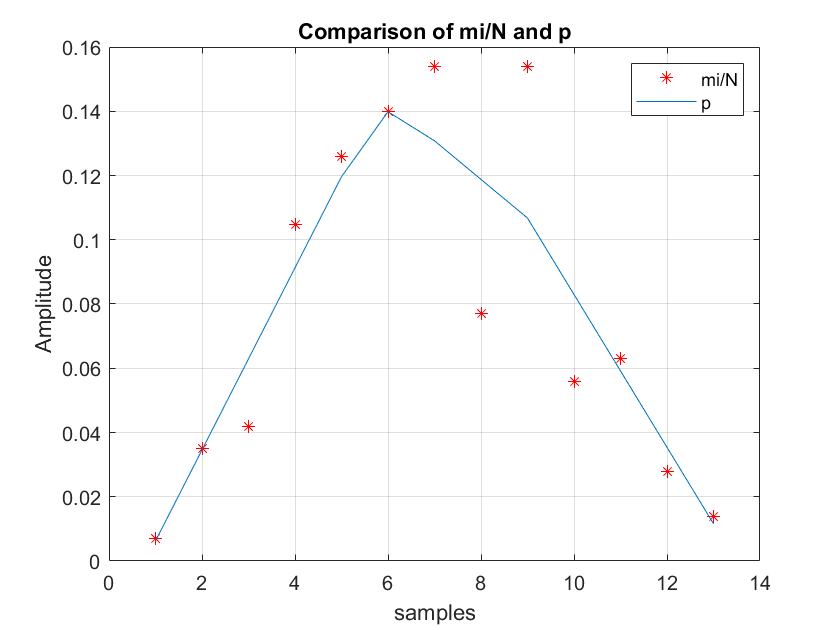

% Comparison:
figure()
plot(m/N,'r*'); % Empirical dist.
hold on
plot(p)
grid on
title('Comparison of mi/N and p')
legend('mi/N','p')
xlabel('samples')
ylabel('Amplitude')